## **Kolmannen asteen yhtälön pinta**

P0=[5,2];
P1=[10,4];
P2=[15,0];
P3=[20,4];

P=[P0;P1;P2;P3];

Määritellään käyrän P1 ja P2 pisteille u:n paikka parametrilla *un*

un=1/2.7;

Seuraavaksi määritellään A matriisi kerrottuna pistematriisilla P.

A=[0,0,0,1;un^3,un^2,un,1;(2*un)^3,(2*un)^2,2*un,1;1,1,1,1]^-1*P;

Määritellään vektori *r,* jota pitkin pursotetaan käyrää.

r=[5,5,5];

P funktiot x,y,z koordinaateille erikseen. Hox! vektorin suuntaista pursotusta ohjataan parametrilla* v*.

Px=@(u,v) [u^3,u^2,u,1]*A(:,1)+r(1)*v;
Py=@(u,v) [u^3,u^2,u,1]*A(:,2)+r(2)*v;
Pz=@(u,v) r(3)*v;

Plotataan data fsurf komennolla. *Hold on / hold off* käskee Matlabia odottamaan jotta kaavioon voidaan lisätä esim. muita käyriä, otsikoita, nimityksiä jne.

fsurf(Px,Py,Pz,[0 1 0 1]);

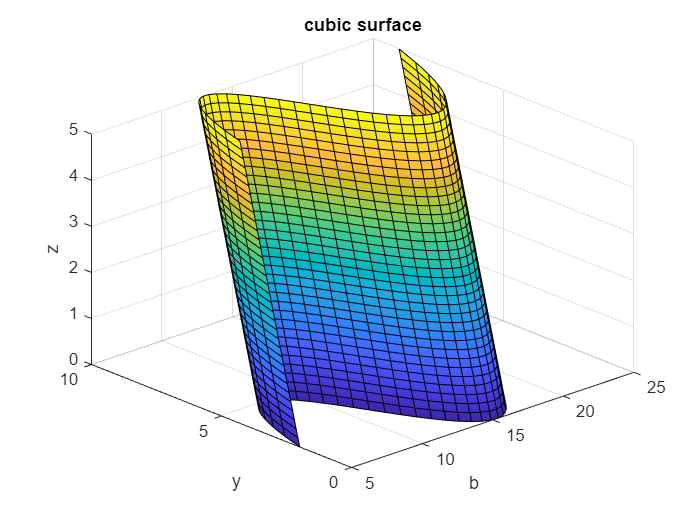

hold on;
xlabel('b'),ylabel('y'),zlabel('z');
title('cubic surface');
hold off;